clc;
close all;
clear variables;

out = evalc('linearizacija_simbolicki');
clearvars -except G L R C E
s = tf('s');

G

G =
 
                      
      2646.8 (s-606.3)
                      
  -------------------------
                           
  (s^2 + 40.92s + 1.618e04)
                           
                           
 
Continuous-time zero/pole/gain model.



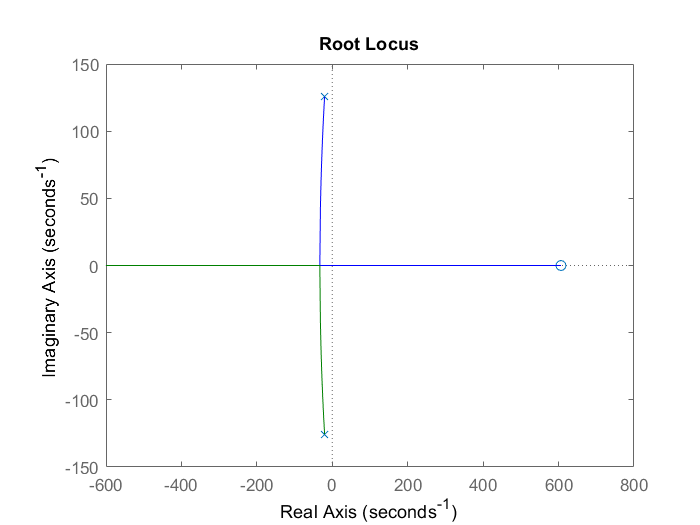

figure()
rlocus(G)

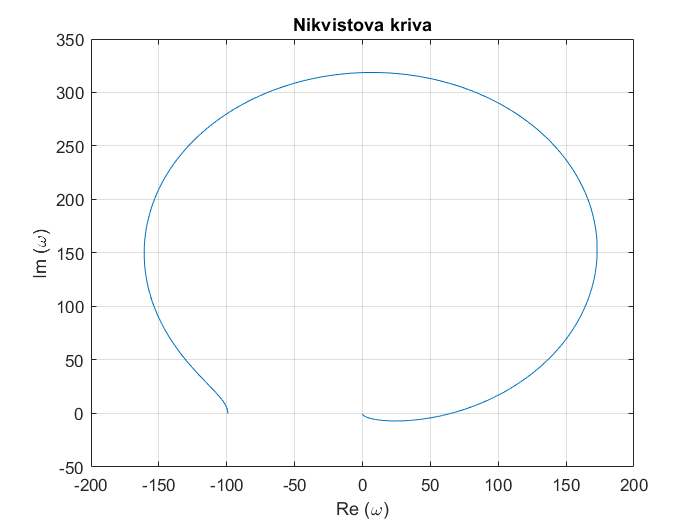


w = 0:0.1:10000;
[re,im] = nyquist(G,w);
re = re(:);
im = im(:);

figure()
plot(re, im)
title("Nikvistova kriva")
xlabel("Re (\omega)")
ylabel("Im (\omega)")
grid on;

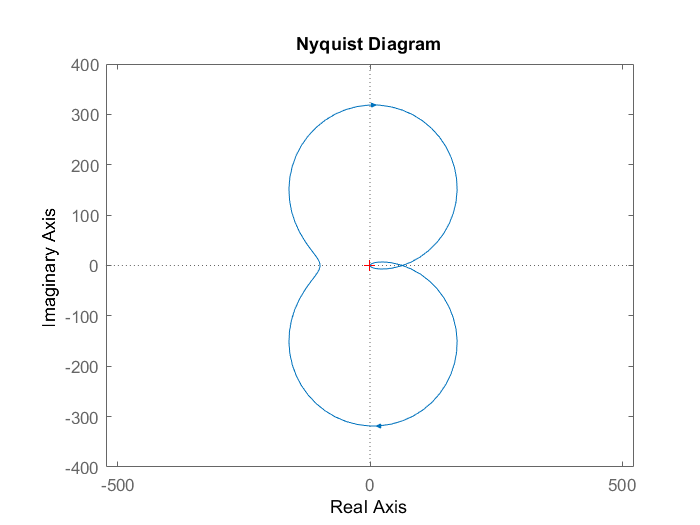

figure()
nyquistplot(G, {0, inf})
axis equal

## Simulacija

% sim_duration = 5; % sec
% sim_file_name = 'buck_boost_sim';
% open_system(sim_file_name)
% out = sim(sim_file_name);
% 